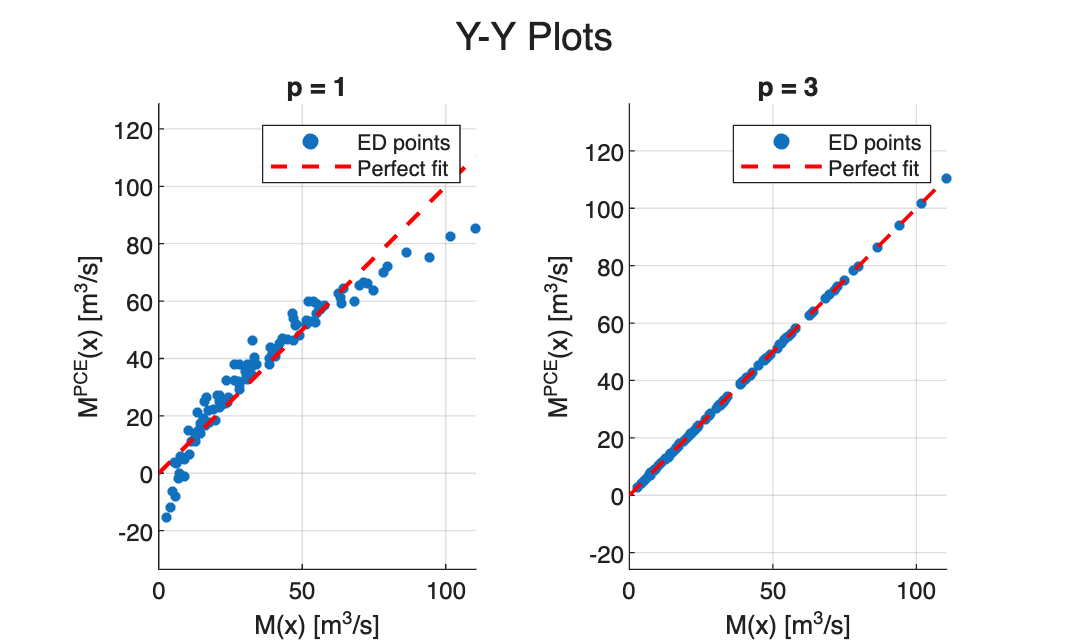

n = 100;
p_list = [1, 3];

[X_ED, Y_ED] = sampleED(n, params, @riverDischarge);

figure;
for idx = 1:2
    p = p_list(idx);
    
    alphas   = create_alphas(numel(params), p);
    Xi_ED    = isoTransform(X_ED, params);
    Psi      = buildPsi(Xi_ED, alphas, params);
    c        = computeCoeffs(Psi, Y_ED);
    Y_PCE_ED = Psi * c;
    
    subplot(1, 2, idx);
    scatter(Y_ED, Y_PCE_ED, 15, 'filled');
    hold on;
    lims = [0, max(Y_ED)];
    plot(lims, lims, 'r--', 'LineWidth', 1.5);
    hold off;
    xlabel('M(x) [m^3/s]');
    ylabel('M^{PCE}(x) [m^3/s]');
    title(sprintf('p = %d', p));
    legend('ED points', 'Perfect fit');
    grid on; axis equal;
end
sgtitle('Y-Y Plots');